clc
clear all
close all
th2u = sym('theta_2u');
th3u = sym('theta_3u');
th4u = sym('theta_4u');
th2d = sym('theta_2d');
th3d = sym('theta_3d');
th4d = sym('theta_4d');
assume(0<th2u<pi)
assume(0<th2d<pi)
assumptions;

O2x = 0;
O2y = 0;
O4ux = sym(100);
O4uy = sym(40);
O4dx = sym(100);
O4dy = sym(-40);
l2 = sym(20);
l4 = sym(30);
l3 = sym(sqrt((O4ux)^2+((O4uy-l4)-(O2y+l2))^2));
l5 = sym(45);

Aux = l2*cos(th2u);
Auy = l2*sin(th2u);
Bux = O4ux + l4*cos(th4u);
Buy = O4uy + l4*sin(th4u);

th2d = th2u + pi;
Adx = l2*cos(th2d);
Ady = l2*sin(th2d);
Bdx = O4dx + l4*cos(th4d);
Bdy = O4dy + l4*sin(th4d);

eq1 = Bux == Aux + l3*cos(th3u);
eq2 = Buy == Auy + l3*sin(th3u);
sol = solve([eq1 eq2],[th3u th4u],"Real",true);
th3u_sol = sol.theta_3u(2);
th4u_sol = sol.theta_4u(2);

eq3 = Bdx == Adx + l3*cos(th3d);
eq4 = Bdy == Ady + l3*sin(th3d);
sol = solve([eq3 eq4],[th3d th4d],"Real",true);
th3d_sol = sol.theta_3d(2);
th4d_sol = sol.theta_4d(2);

BuxNew = subs(Bux,th4u,th4u_sol);
BuyNew = subs(Buy,th4u,th4u_sol);
symvar([BuxNew BuyNew]);

BdxNew = subs(Bdx,th4d,th4d_sol);
BdyNew = subs(Bdy,th4d,th4d_sol);
symvar([BdxNew BdyNew]);

th5u = sym(th4u_sol + pi/2);
Cux = O4ux + l5*cos(th5u);
Cuy = O4uy + l5*sin(th5u);

th5d = sym(th4d_sol - pi/2);
Cdx = O4dx + l5*cos(th5d);
Cdy = O4dy + l5*sin(th5d);

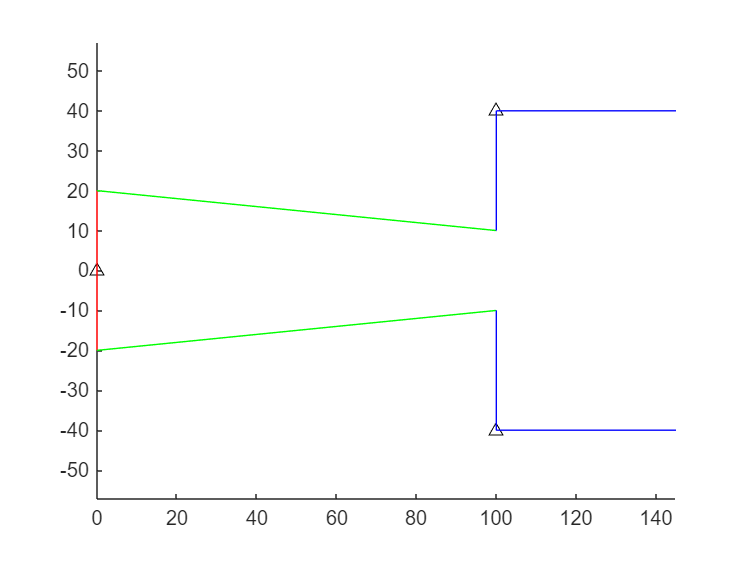

hu_link2 = @(t) plot([O2x subs(Aux,t)], ...
                    [O2y subs(Auy,t)], '-r');
hu_link3 = @(t) plot([subs(Aux,t) subs(BuxNew,t) subs(Aux,t)], ...
                    [subs(Auy,t) subs(BuyNew,t) subs(Auy,t)], '-g');
hu_link4 = @(t) plot([O4ux subs(BuxNew,t)], ...
                    [O4uy subs(BuyNew,t)], '-b');
hu_link5 = @(t) plot([O4ux subs(Cux,t)], ...
                    [O4uy subs(Cuy,t)], '-b');

hd_link2 = @(t) plot([O2x subs(Adx,t)], ...
                    [O2y subs(Ady,t)], '-r');
hd_link3 = @(t) plot([subs(Adx,t) subs(BdxNew,t) subs(Adx,t)], ...
                    [subs(Ady,t) subs(BdyNew,t) subs(Ady,t)], '-g');
hd_link4 = @(t) plot([O4dx subs(BdxNew,t)], ...
                    [O4dy subs(BdyNew,t)], '-b');
hd_link5 = @(t) plot([O4dx subs(Cdx,t)], ...
                    [O4dy subs(Cdy,t)], '-b');

figure()
hold on
plot(O2x,O2y,'k^')
plot(O4ux,O4uy,'k^')
plot(O4dx,O4dy,'k^')

hu_link2(pi/2)
hu_link3(pi/2)
hu_link4(pi/2)
hu_link5(pi/2)
hd_link2(pi/2)
hd_link3(pi/2)
hd_link4(pi/2)
hd_link5(pi/2)
hold off
axis equal

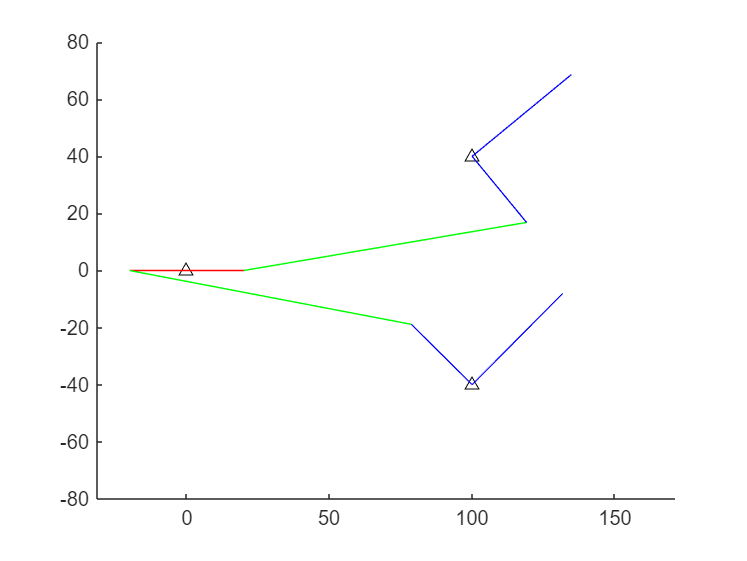


figure()
hold on
plot(O2x,O2y,'k^')
plot(O4ux,O4uy,'k^')
plot(O4dx,O4dy,'k^')

fanimator(hu_link2)
fanimator(hu_link3)
fanimator(hu_link4)
fanimator(hu_link5)
fanimator(hd_link2)
fanimator(hd_link3)
fanimator(hd_link4)
fanimator(hd_link5)

hold off
axis equal

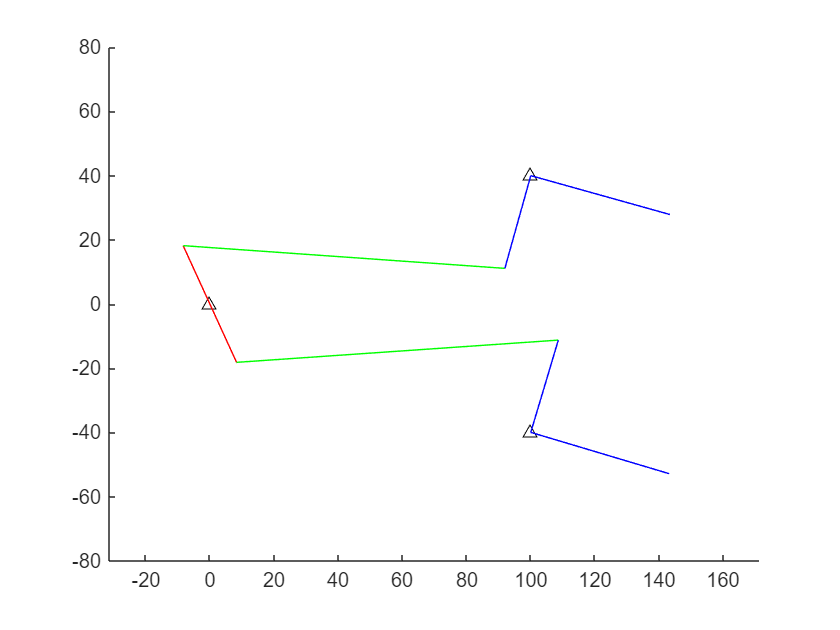

playAnimation('AnimationRange',[0 pi],'FrameRate',10)

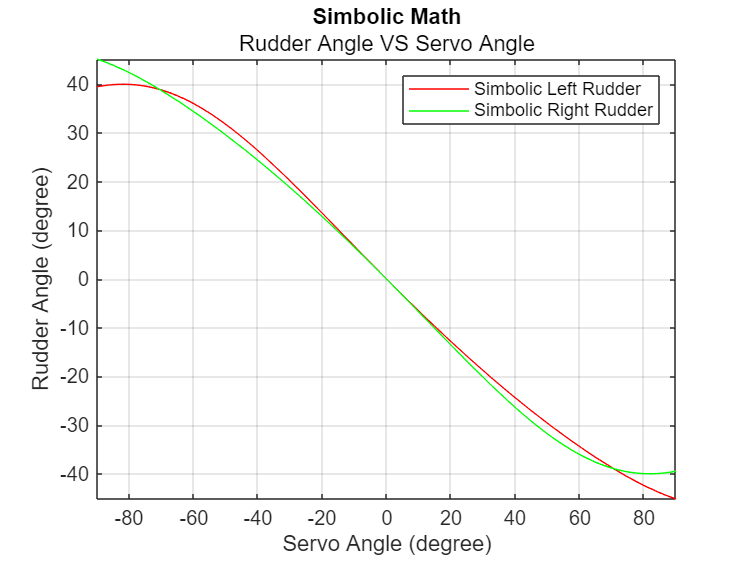

th2uplot = rad2deg(th2u) - 90;
fplot(th2uplot,rad2deg(th5u),[0 pi],'r')
hold on
fplot(th2uplot,rad2deg(th5d),[0 pi],'g')
hold off
grid on
title('Simbolic Math','Rudder Angle VS Servo Angle')
xlabel('Servo Angle (degree)')
ylabel('Rudder Angle (degree)')
legend('Simbolic Left Rudder','Simbolic Right Rudder')

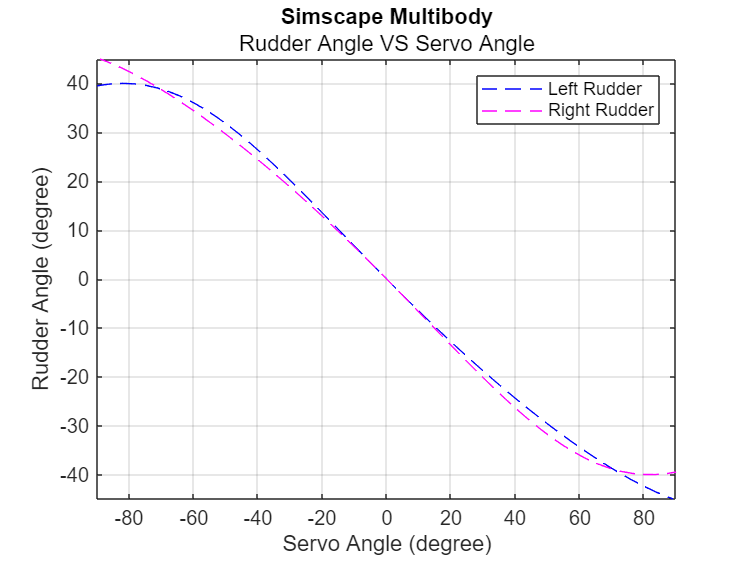

plot(out.simout.Time*18-90,out.simout.Data,'--b')
hold on
plot(out.simout1.Time*18-90,out.simout1.Data,'--m')
hold off
xlim([-90 90])
ylim([-45 45])
grid on
title('Simscape Multibody','Rudder Angle VS Servo Angle')
xlabel('Servo Angle (degree)')
ylabel('Rudder Angle (degree)')
legend('Left Rudder','Right Rudder')

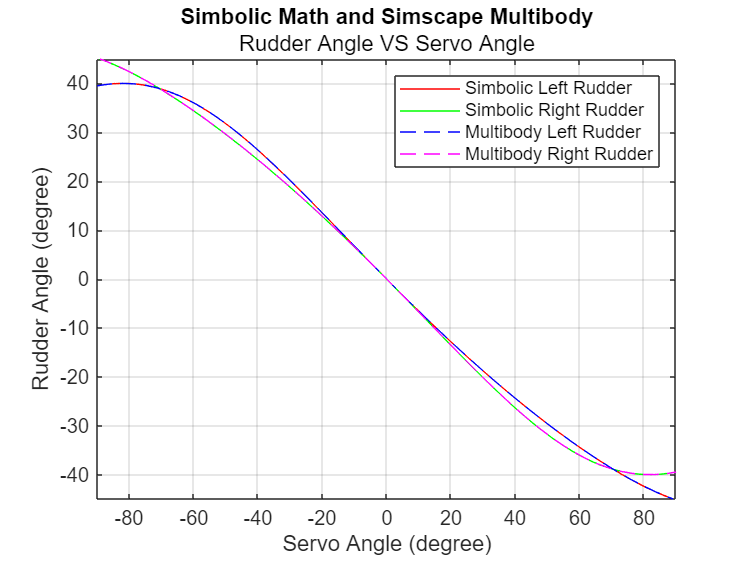

th2uplot = rad2deg(th2u) - 90;
fplot(th2uplot,rad2deg(th5u),[0 pi],'r')
hold on
fplot(th2uplot,rad2deg(th5d),[0 pi],'g')
plot(out.simout.Time*18-90,out.simout.Data,'--b')
plot(out.simout1.Time*18-90,out.simout1.Data,'--m')
hold off

title('Simbolic Math and Simscape Multibody','Rudder Angle VS Servo Angle')
xlabel('Servo Angle (degree)')
ylabel('Rudder Angle (degree)')
xlim([-90 90])
ylim([-45 45])
grid on
legend('Simbolic Left Rudder','Simbolic Right Rudder','Multibody Left Rudder','Multibody Right Rudder')

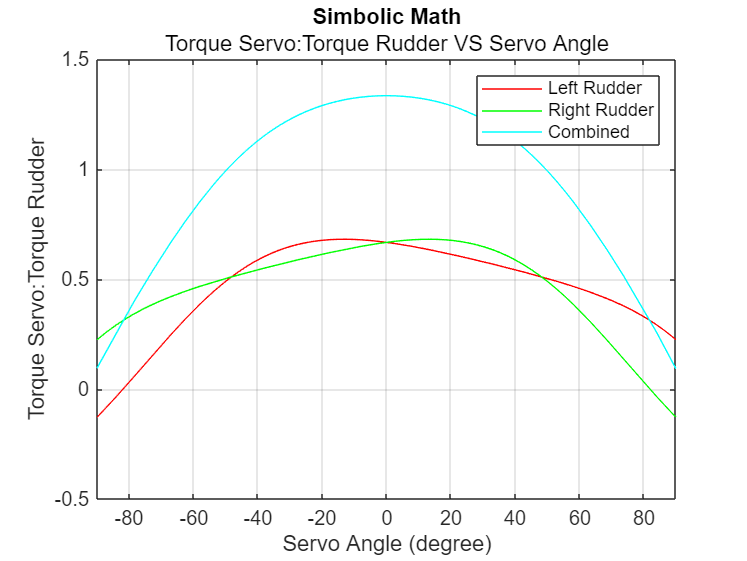

th2uplot = rad2deg(th2u) - 90;
fplot(th2uplot,-diff(th5u),'r')
hold on
fplot(th2uplot,-diff(th5d),'g')
fplot(th2uplot,-diff(th5u)-diff(th5d),'c')
hold off
xlim([-90 90])
ylim([-0.5 1.5])
grid on
title('Simbolic Math','Torque Servo:Torque Rudder VS Servo Angle')
xlabel('Servo Angle (degree)')
ylabel('Torque Servo:Torque Rudder')
legend('Left Rudder','Right Rudder','Combined')

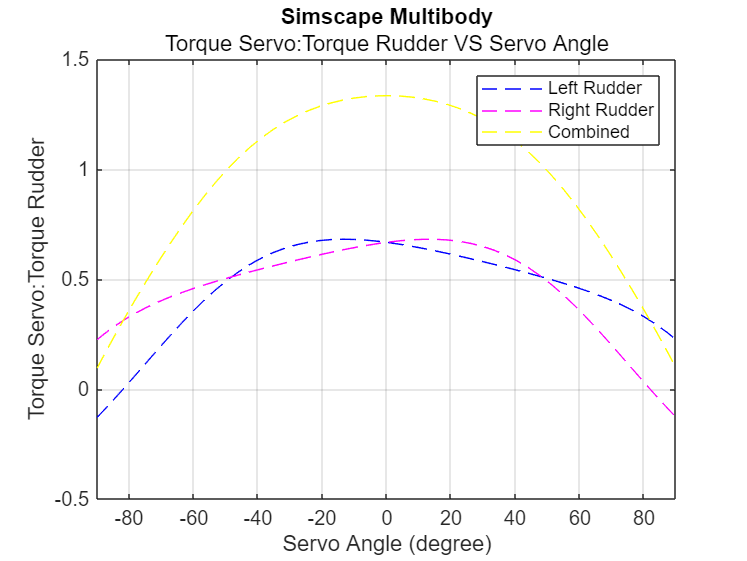

plot(out.simout2.Time*18-90,out.simout2.Data,'--b')
hold on
plot(out.simout3.Time*18-90,out.simout3.Data,'--m')
plot(out.simout4.Time*18-90,out.simout4.Data,'--y')
hold off
xlim([-90 90])
ylim([-0.5 1.5])
grid on
title('Simscape Multibody','Torque Servo:Torque Rudder VS Servo Angle')
xlabel('Servo Angle (degree)')
ylabel('Torque Servo:Torque Rudder')
legend('Left Rudder','Right Rudder','Combined')

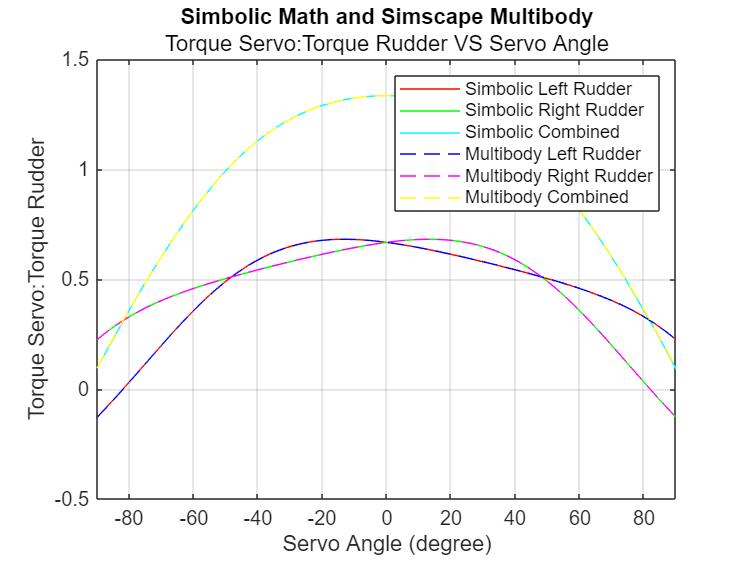

th2uplot = rad2deg(th2u) - 90;
fplot(th2uplot,-diff(th5u),'r')
hold on
fplot(th2uplot,-diff(th5d),'g')
fplot(th2uplot,-diff(th5u)-diff(th5d),'c')
plot(out.simout2.Time*18-90,out.simout2.Data,'--b')
plot(out.simout3.Time*18-90,out.simout3.Data,'--m')
plot(out.simout4.Time*18-90,out.simout4.Data,'--y')
hold off

title('Simbolic Math and Simscape Multibody','Torque Servo:Torque Rudder VS Servo Angle')
xlabel('Servo Angle (degree)')
ylabel('Torque Servo:Torque Rudder')
xlim([-90 90])
ylim([-0.5 1.5])
grid on
legend('Simbolic Left Rudder','Simbolic Right Rudder', ...
    'Simbolic Combined', ...
    'Multibody Left Rudder','Multibody Right Rudder', ...
    'Multibody Combined')